# concatWavAll

Concatenate 10-min 48-ch wav files into a MAT-file

clearvars

## Set parameters

setDir = 'C:\Users\510PAS\PhD\Data\NW_2019\DesGros\20190825_AAA2B';      % Set directory

spec = 1;                                                               % Plot Spectrogram
singleCh = 0;
cleanData = 0;

## Get all the file names in the directory

cd(setDir)
chFiles = dir('*.h5');                              % Find all the files in the dir
nFiles = length(chFiles);
arrData = double([]);                                  % make empty arrray 
timeVec = []; 
h5disp(chFiles(1).name);

HDF5 NW_2019_A2__20190825_220710_00_0140.h5 
Group '/' 
    Dataset 'BUS_CURRENTS' 
        Size:  4x1117
        MaxSize:  4xInf
        Datatype:   H5T_IEEE_F32LE (single)
        ChunkSize:  1x1117
        Filters:  none
        FillValue:  0.000000
    Dataset 'DATA_SAMPLES' 
        Size:  48x1396250
        MaxSize:  48xInf
        Datatype:   H5T_IEEE_F32LE (single)
        ChunkSize:  1x1250
        Filters:  none
        FillValue:  0.000000
        Attributes:
            'start_time':  1566770865.969610
            'end_time':  1566771424.469610
            'sample_rate':  2500
            'bits_per_sample':  16
            'gain':  90
    Dataset 'TIMESTAMP' 
        Size:  1117
        MaxSize:  1117
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


## Loop through the directory and extract the single channels

for iFile = 1:nFiles
    data = h5read(chFiles(iFile).name,'/DATA_SAMPLES')';                   % Read in the acoustic data
    if singleCh
        data = data(:,1); %#ok<UNRCH> 
    end
    gain = h5readatt(chFiles(iFile).name,'/DATA_SAMPLES','gain');
    %factor = (5/65535)*10^-(double(gain)/20);      %factor = 10^(-double(gain)/20);
    %factor = (5/2)*10^-(double(gain)/20);
    factor = (2/5)*10^-(double(gain)/20);
    data = data.*factor;
    time = h5read(chFiles(iFile).name,'/TIMESTAMP');
    time = datetime(time,'ConvertFrom','epochtime','Format','dd-MMM-yyyy HH:mm:ss.S');
    arrData = vertcat(arrData, data);
    timeVec = vertcat(timeVec, time);
    fprintf('Just finished iteration #%d\n', iFile);
end

Just finished iteration #1
Just finished iteration #2
Just finished iteration #3
Just finished iteration #4


## Plot spectrogram

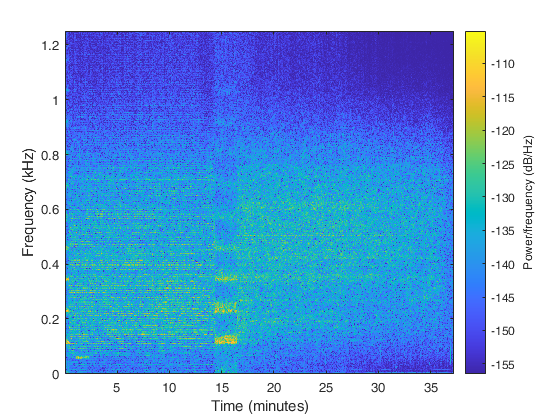

if spec == 1
    dur=0.5; fs=2500;
    winSize=round(fs*dur);
    overlap=round(winSize/2);
    fftsize=winSize;
    figure
    spectrogram(arrData(:,1),winSize,overlap,fftsize,fs,'yaxis')
    saveas(gcf,'Spectrogram.png')
end

## Clean data

if cleanData
    disp('Cleaning data')
    arrData = filloutliers(arrData,'clip','ThresholdFactor',200);
end

## Save the file as .mat

saveName = fullfile(setDir,'\proc\allCh.mat');
matObj = matfile(saveName,'Writable',true);
matObj.data = arrData;
matObj.time = timeVec;
clear all